clear; clc;
cvx_clear;

addpath './../classes'

% BB84 states

s0  = [1;0]

s0 =      1
     0


s1  = [0;1]

s1 =      0
     1


sp  = [1;1]/sqrt(2)

sp =     0.7071
    0.7071


sm  = [1;-1]/sqrt(2)

sm =     0.7071
   -0.7071


spi =    0.7071 + 0.0000i
   0.0000 + 0.7071i


smi =    0.7071 + 0.0000i
   0.0000 - 0.7071i



states = [s0, s1, sp, sm  ]

states =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.7071 + 0.0000i  -0.7071 + 0.0000i   0.0000 + 0.7071i   0.0000 - 0.7071i


% Pauli matrices

E = [1 0; 0 1];
X = [0 1; 1 0];
Y = [0 -i; i 0];
Z = [1 0; 0 -1];

% 1. Definition der Achsenbereiche
lambda_vec = linspace(0, 1, 100); 
mu_vec = linspace(0, 0.75, 100);

% 2. Matrix für die Ergebnisse voralokieren (wichtig für die Performance!)
Bob = zeros(length(lambda_vec), length(mu_vec));
Entanglement = zeros(length(lambda_vec), length(mu_vec));

% 3. Geschachtelte for-Schleife
for i = 1:length(mu_vec)         % Schleife über die Zeilen (y-Werte)
    fprintf(" i =  %d \n", i);
    for j = 1:length(lambda_vec)     % Schleife über die Spalten (x-Werte)
        % Aktuelle Koordinaten holen
        lambda = lambda_vec(j);
        mu = mu_vec(i);

        cloner = SDP_1to2_AsymmetricCloning(states, lambda);
        [primal_optimum, J] = cloner.solvePrimal();
        kraus_ops = Utils.getKrausOperators(J,2,4);
        
        rho_in = s0*s0';
        rho_out =Utils.applyChannel(kraus_ops,rho_in);

        K0 = sqrt(1-mu)*E;
        K1 = sqrt(mu/3)*X;
        K2 = sqrt(mu/3)*Y;
        K3 = sqrt(mu/3)*Z;
        
        N0 = kron( K0, E);
        N1 = kron( K1, E);
        N2 = kron( K2, E);
        N3 = kron( K3, E);
        
        rho_final = N0*rho_out*N0' + N1*rho_out*N1' + N2*rho_out*N2' + N3*rho_out*N3';
        
        rho_Bob = PartialTrace( rho_final,[2],[2,2]);
        fidelity_Bob = real( trace(rho_in*rho_Bob ) );
        Bob(i, j) = fidelity_Bob;

        con = Concurrence(rho_final);
        Entanglement(i, j) = con;
    end
end

 i =  1 
 i =  2 
 i =  3 
 i =  4 
 i =  5 
 i =  6 
 i =  7 
 i =  8 
 i =  9 
 i =  10 
 i =  11 
 i =  12 
 i =  13 
 i =  14 
 i =  15 
 i =  16 
 i =  17 
 i =  18 
 i =  19 
 i =  20 


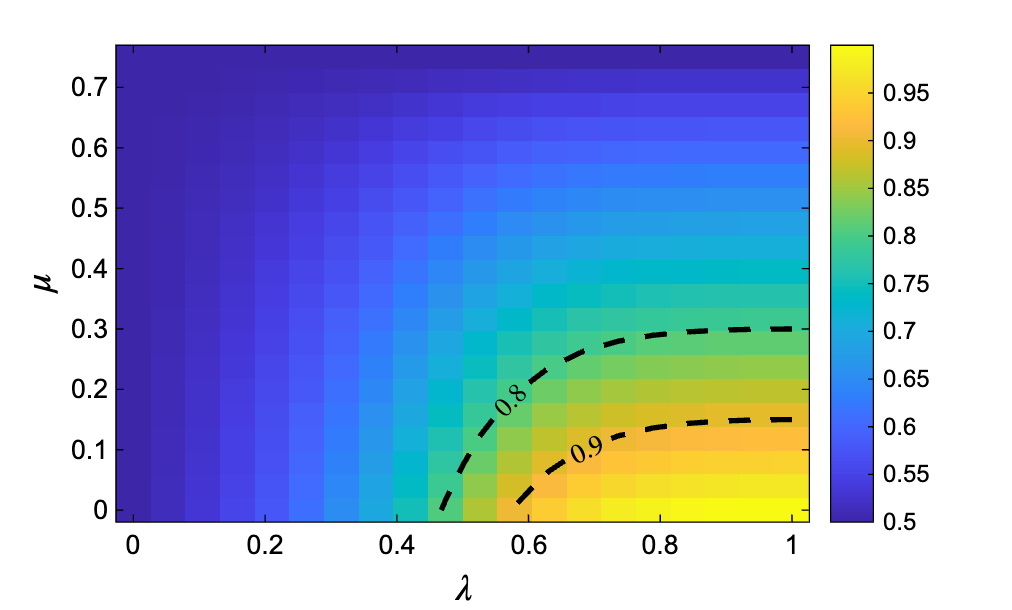

% 4. Visualisierung als Heatmap
figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Bob); % Erstellt die Heatmap
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 

% 2. Konturlinie und Beschriftung
target_z = 0.9;
[C, h] = contour(lambda_vec, mu_vec, Bob, [target_z, target_z], ...
                 'LineColor', 'k', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

clabel(C, h, 'FontSize', 10, 'Color', 'k', 'Interpreter', 'latex');

target_z = 0.8;
[C, h] = contour(lambda_vec, mu_vec, Bob, [target_z, target_z], ...
                 'LineColor', 'k', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

clabel(C, h, 'FontSize', 10, 'Color', 'k', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 

% --- FARBANPASSUNGEN FÜR ACHSEN UND TEXT ---

% Achsen-Linien und Skalenwerte (Ticks) auf Schwarz setzen
set(gca, 'XColor', 'k', 'YColor', 'k');

% Beschriftungen explizit in Schwarz ('Color', 'k')
xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
%title('Heatmap der Funktion $F_{Bob}$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 16);

% Optional: Falls die Colorbar-Beschriftung auch schwarz sein soll
cb = colorbar;
cb.Color = 'k'; % Setzt den Rahmen und die Zahlen der Colorbar auf Schwarz

% --- EXPORT ---
exportgraphics(gcf, './figures/BB84Attack_Fidelity_4States.jpg', 'Resolution', 300);

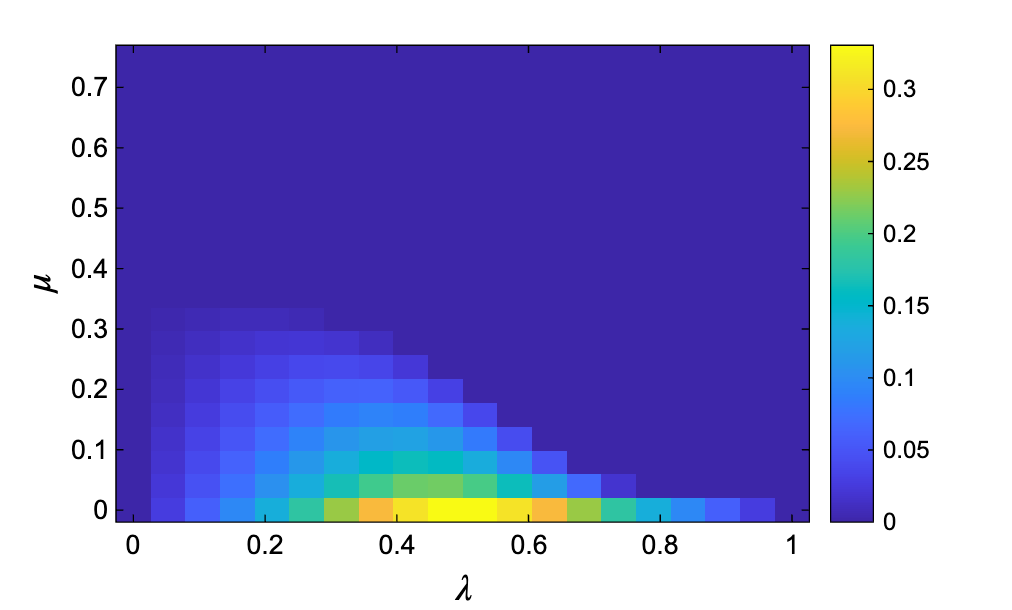

% 4. Visualisierung als Heatmap
figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Entanglement); % Erstellt die Heatmap
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 

% 2. Konturlinie
target_z = 0.85;
[C, h] = contour(lambda_vec, mu_vec, Entanglement, [target_z, target_z], ...
                 'LineColor', 'w', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

% 3. Beschriftung an der Linie (bleibt Weiß für Kontrast auf der Map)
clabel(C, h, 'FontSize', 10, 'Color', 'w', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 

% --- FARBANPASSUNGEN FÜR ACHSEN UND TEXT ---

% Achsen-Linien und Skalenwerte (Ticks) auf Schwarz setzen
set(gca, 'XColor', 'k', 'YColor', 'k');

% Beschriftungen explizit in Schwarz ('Color', 'k')
xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
%title('Verschränkung', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 16);

% Optional: Falls die Colorbar-Beschriftung auch schwarz sein soll
cb = colorbar;
cb.Color = 'k'; % Setzt den Rahmen und die Zahlen der Colorbar auf Schwarz

exportgraphics(gcf, './figures/BB84Attack_Concurrence_4States.jpg', 'Resolution', 300);